# Task 1

disp ("Task 1")

Task 1


A = [5 0 -3 0 0
    1 3 0 -1 0
    0 1 7 0 -2
    0 0 1 22 0
    0 0 0 1 8];
disp("Компактное представление А:")
AN = sparse(A)

AN =    (1,1)        5
   (2,1)        1
   (2,2)        3
   (3,2)        1
   (1,3)       -3
   (3,3)        7
   (4,3)        1
   (2,4)       -1
   (4,4)       22
   (5,4)        1
   (3,5)       -2
   (5,5)        8


disp("Восстановленная матрица:")
AF = full(AN)

AF =      5     0    -3     0     0
     1     3     0    -1     0
     0     1     7     0    -2
     0     0     1    22     0
     0     0     0     1     8


## Task 2

disp ("Task 2")

Task 2


irow = [1 1 2 2 2 3 3 3 4 4 5 5];
jcol = [1 3 1 2 4 2 3 5 3 4 4 5];
nzer = [5 -3 1 3 -1 1 7 -2 1 22 1 8];
disp("Компактное представление А:")
AN = sparse(irow, jcol, nzer, 5, 5)

AN =    (1,1)        5
   (2,1)        1
   (2,2)        3
   (3,2)        1
   (1,3)       -3
   (3,3)        7
   (4,3)        1
   (2,4)       -1
   (4,4)       22
   (5,4)        1
   (3,5)       -2
   (5,5)        8


disp("Восстановленная матрица:")
AF = full(AN)

ans =      5     0    -3     0     0
     1     3     0    -1     0
     0     1     7     0    -2
     0     0     1    22     0
     0     0     0     1     8



if (AN == A)
    disp("Проверка выполнена")
end

whos A AN

  Name      Size            Bytes  Class     Attributes

  A         5x5               200  double              
  AN        5x5               240  double    sparse    



Матрицы равны!


## Task 3

disp ("Task 3")
disp("Все ненулевые элементы матрицы:")
[ir, jr, nz] = find(AN)

## Task 4

disp ("Task 4")

Task 4


A = load("matrix.dat")

A =      1     1     5
     2     1     1
     2     2     3
     3     2     1
     1     3    -3
     3     3     7
     4     3     1
     2     4    -1
     4     4    22
     5     4     1


disp("Компактное представление А:")

Компактное представление А:


AN = spconvert(A)

AN =    (1,1)        5
   (2,1)        1
   (2,2)        3
   (3,2)        1
   (1,3)       -3
   (3,3)        7
   (4,3)        1
   (2,4)       -1
   (4,4)       22
   (5,4)        1
   (3,5)       -2
   (5,5)        8


disp("Восстановленная матрица:")

Восстановленная матрица:


AF = full(AN)

AF =      5     0    -3     0     0
     1     3     0    -1     0
     0     1     7     0    -2
     0     0     1    22     0
     0     0     0     1     8


## Task 5

disp ("Task 5")

Task 5


DN = [1 5 0
     1 3 0
     1 7 -3
     1 22 -1
     0 8 -2];
d = [-1 0 2];
A = spdiags(DN, d, 5, 5);
disp("Восстановленная матрица:")
AF = full(A)

AF =      5     0    -3     0     0
     1     3     0    -1     0
     0     1     7     0    -2
     0     0     1    22     0
     0     0     0     1     8


## Task 6

disp("Task 6")
B = [4 1 0 0 1 0
     1 4 1 0 0 0
     0 1 4 0 0 0
     0 0 0 4 0 1
     1 0 0 0 4 1
     0 0 0 1 1 4];

disp("Первый способ:")
B1 = load("matrix2.dat");
disp("Компактное представление А:")
AN1 = spconvert(B1)
disp("Восстановленная матрица:")
AF1 = full(AN1)

whos B AN1

disp("Второй способ:")
B2 =[1 0 1 4 0 0 0
     0 0 1 4 1 0 0
     0 0 0 4 1 0 0
     0 1 0 4 0 0 0
     0 0 1 4 0 0 1
     0 0 0 4 1 1 0];
d = [-4 -2 -1 0 1 2 4];
disp("Компактное представление А:")
AN2 = spdiags(B2, d, 6, 6)
disp("Восстановленная матрица:")
AF2 = full(AN2)

whos B AN2

## Task 7

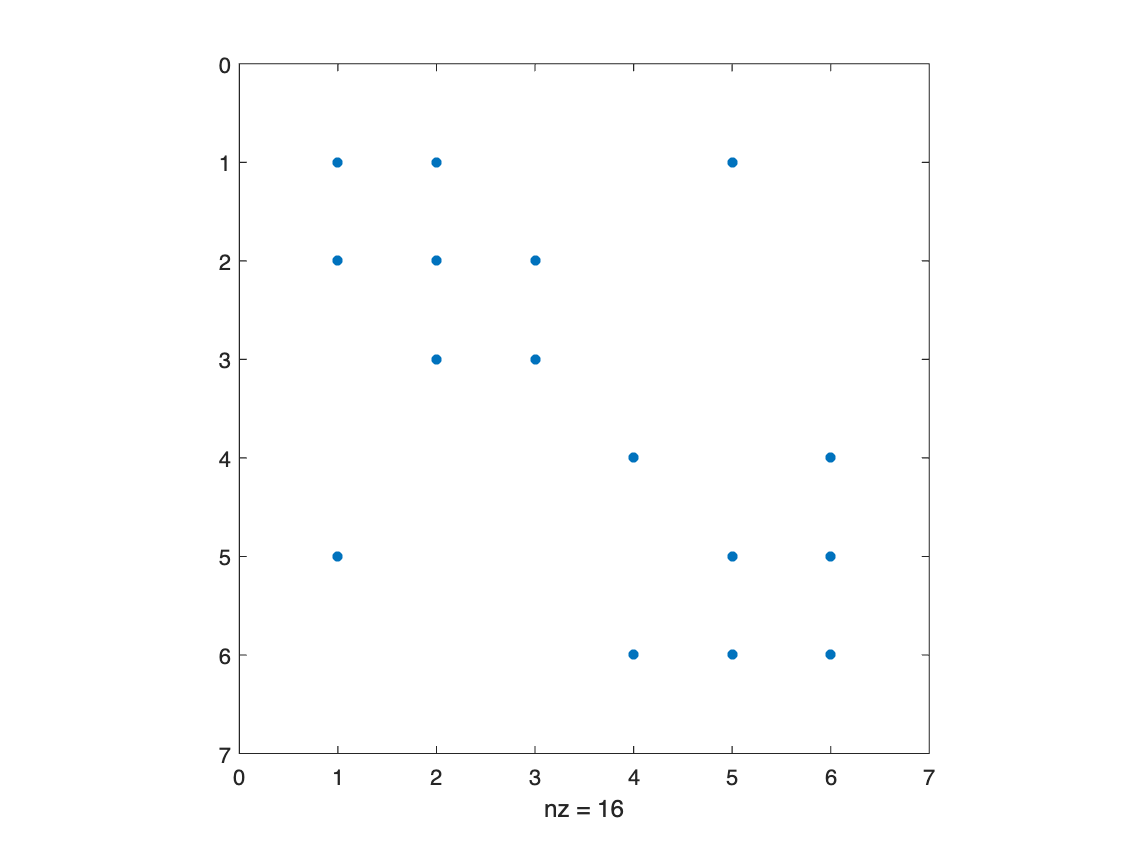

figure(name = "Task 7")
B = [4 1 0 0 1 0
     1 4 1 0 0 0
     0 1 4 0 0 0
     0 0 0 4 0 1
     1 0 0 0 4 1
     0 0 0 1 1 4];
spy(B)

## Task 8

disp("Task 8")

Task 8


AN = load("matrix2.dat");
B = spconvert(AN);
sorted = symrcm(B);
B = full(B(sorted, sorted))

B =      4     1     0     0     0     0
     1     4     1     0     0     0
     0     1     4     1     0     0
     0     0     1     4     1     0
     0     0     0     1     4     1
     0     0     0     0     1     4


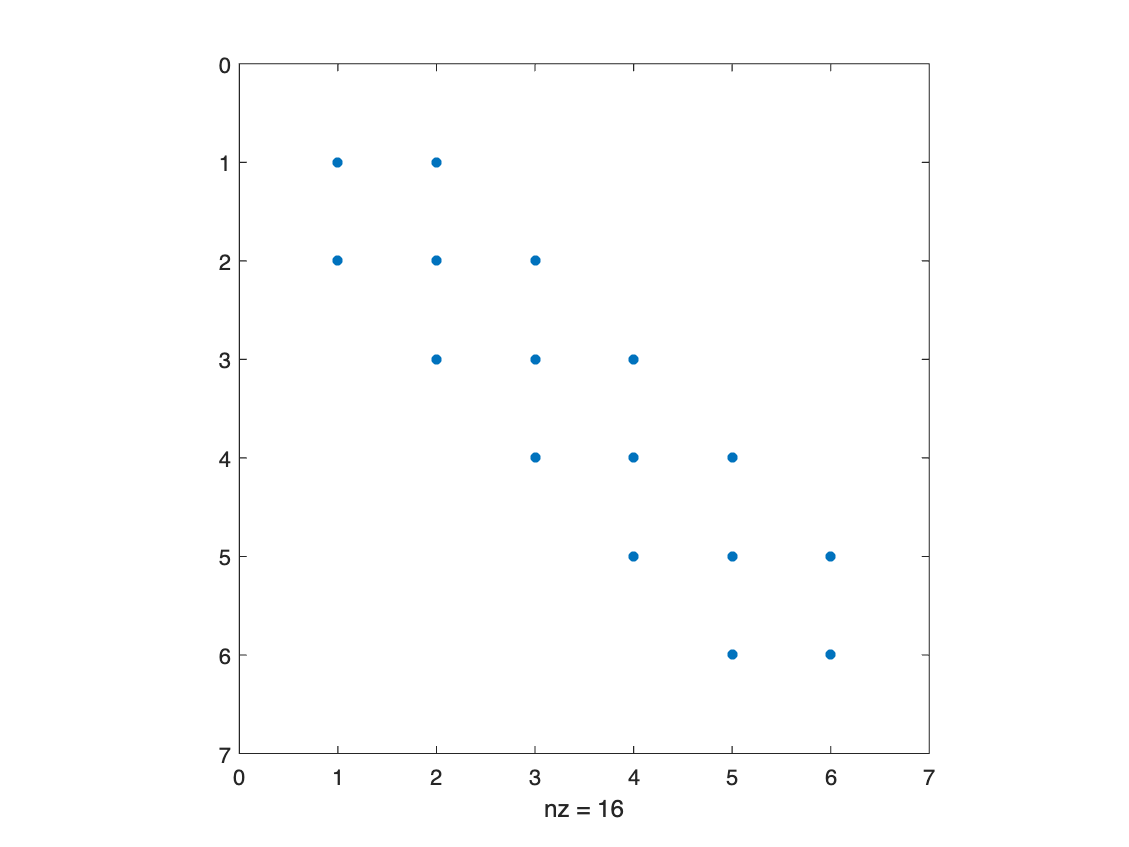

figure(name = "Task 8")
spy(B)

## Task 9

disp("Task 9")

Task 9


B = [7 1 1 1 1
     1 7 0 0 0
     1 0 7 0 0
     1 0 0 7 0
     1 0 0 0 7];
BN = sparse(B)

BN =    (1,1)        7
   (2,1)        1
   (3,1)        1
   (4,1)        1
   (5,1)        1
   (1,2)        1
   (2,2)        7
   (1,3)        1
   (3,3)        7
   (1,4)        1
   (4,4)        7
   (1,5)        1
   (5,5)        7


R1 = chol(BN)

R1 =    (1,1)       2.6458
   (1,2)       0.3780
   (2,2)       2.6186
   (1,3)       0.3780
   (2,3)      -0.0546
   (3,3)       2.6180
   (1,4)       0.3780
   (2,4)      -0.0546
   (3,4)      -0.0557
   (4,4)       2.6175
   (1,5)       0.3780
   (2,5)      -0.0546
   (3,5)      -0.0557
   (4,5)      -0.0569
   (5,5)       2.6168


L1 = chol(BN, "lower")

L1 =    (1,1)       2.6458
   (2,1)       0.3780
   (3,1)       0.3780
   (4,1)       0.3780
   (5,1)       0.3780
   (2,2)       2.6186
   (3,2)      -0.0546
   (4,2)      -0.0546
   (5,2)      -0.0546
   (3,3)       2.6180
   (4,3)      -0.0557
   (5,3)      -0.0557
   (4,4)       2.6175
   (5,4)      -0.0569
   (5,5)       2.6168


sorted = symrcm(B);
R2 = chol(B(sorted, sorted));
disp("Результаты:")

Результаты:


before = nnz(R1)

before = 15

after = nnz(R2)

after = 9